# Workspace & Robot Plotting

clc; clear; close all;
load_data_kinematics;

plot_WS_directory = ['C:\Users\miche\OneDrive - unibs.it\University\Magistrale - UNIBS\' ...
                      '1_Primo Anno\Servosystems & Robotics\Servosystems & Robotics Project\src\WS & Robot Plotting\plots'];

## Old Version

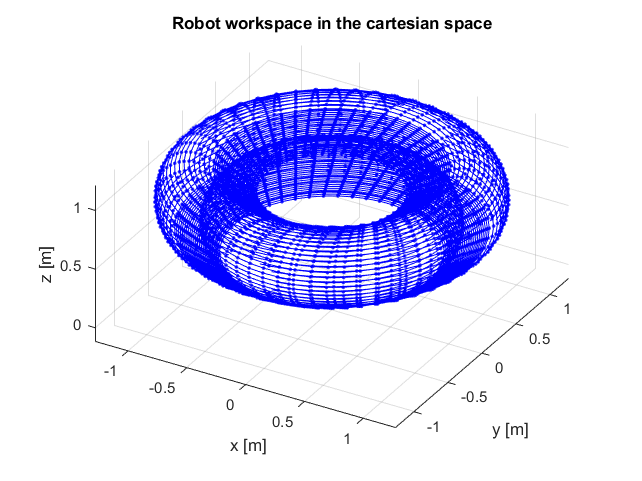

figure
plot_workspace_OLD(L,angle,pos_limits,gcf)

## Current Version

### Workspace

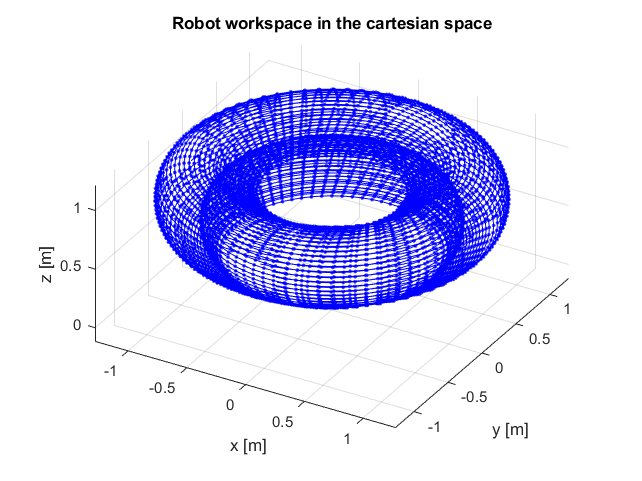

nPoints = [70 15 25];

figure
plot_workspace(L,angle,pos_limits,gcf,nPoints)

set(gcf,'renderer','painters');
exportgraphics(gcf, strcat(plot_WS_directory,'\WS_3D.pdf'))

### Manipulator

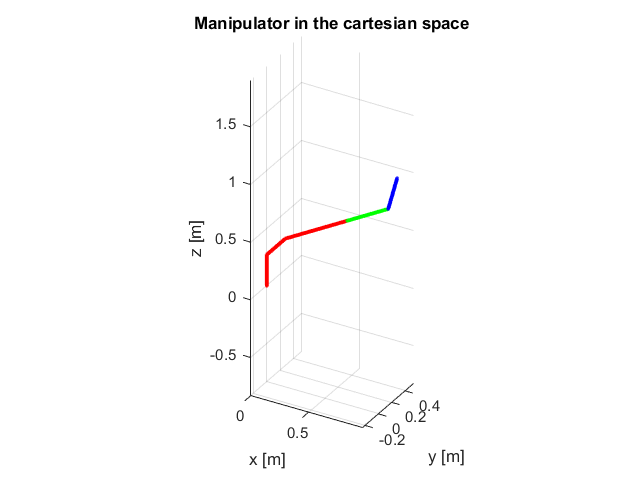

Q = {0.5*pi; 0.3; 0.25*pi};

figure
plot_robot(Q,L,angle,gcf);
grid on
axis equal
view(30,30)
xlabel('x [m]'); ylabel('y [m]'); zlabel('z [m]')
title('Manipulator in the cartesian space')

## Robot and WS according to UNI EN ISO 9787 - Old version (plot3)

Important! UNI EN ISO 9787 would suggest to choose X1 aligned with Cw. However, in particular situations, free choice is admissible. In this case, it is not possible to strictly follow the rule, unless you choose a very uncomfortable frame of reference. Hence, free choice is adopted.

### Projection on $X_1 Z_1$ Plane

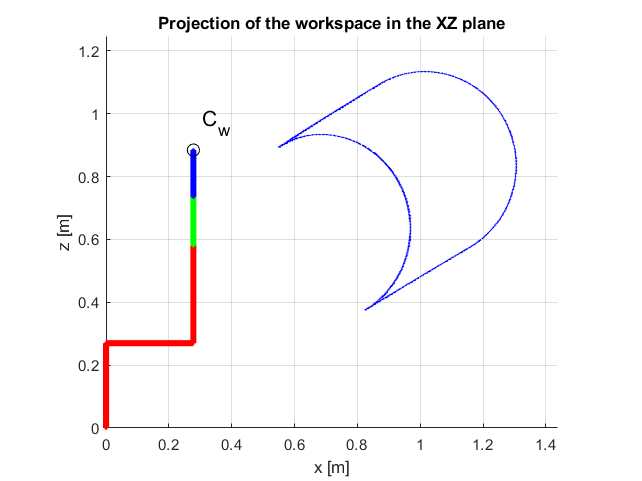

% Workspace
nPoints = [500 100 200];

figure
workspace_XZ_projection_OLD(L,angle,pos_limits,gcf,nPoints)

% Robot with all its axes in their median position (Cw: center of the working space)
Qcw = [median(pos_limits(1:2)); median(pos_limits(3:4)); median(pos_limits(5:6))];
Qcw = num2cell(Qcw);
plot_robot_bold(Qcw,L,angle,gcf)

### Projection on $X_1 Y_1$ Plane

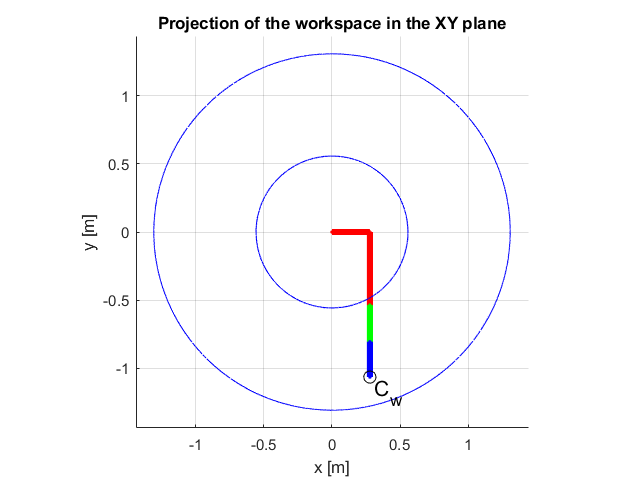

% Workspace
nPoints = [1000 100 200];

figure
workspace_XY_projection_OLD(L,angle,pos_limits,gcf,nPoints)

% Robot with all its axes in their median position (Cw: center of the working space)
Qcw = [median(pos_limits(1:2)); median(pos_limits(3:4)); median(pos_limits(5:6))];
Qcw = num2cell(Qcw);
plot_robot_bold(Qcw,L,angle,gcf)

## Robot and WS according to UNI EN ISO 9787 - Current version (plot + patch)

Important! UNI EN ISO 9787 would suggest to choose X1 aligned with Cw. However, in particular situations, free choice is admissible. In this case, it is not possible to strictly follow the rule, unless you choose a very uncomfortable frame of reference. Hence, free choice is adopted.

### Projection on $X_1 Z_1$ Plane

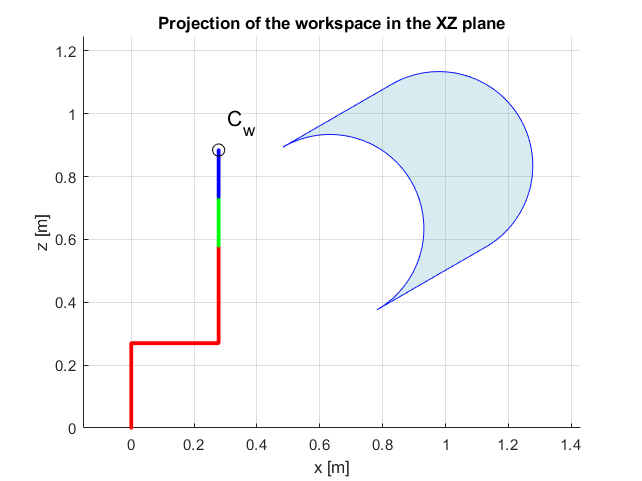

% Workspace
nPoints = [500 100 200];

figure
workspace_XZ_projection(L,angle,pos_limits,gcf,nPoints)

% Robot with all its axes in their median position (Cw: center of the working space)
Qcw = [median(pos_limits(1:2)); median(pos_limits(3:4)); median(pos_limits(5:6))];
Qcw = num2cell(Qcw);
plot_robot_bold_2D(Qcw,L,angle,gcf,[1 3])

set(gcf,'renderer','painters');
exportgraphics(gcf, strcat(plot_WS_directory,'\WS_XZ.pdf'))

### Projection on $X_1 Y_1$ Plane

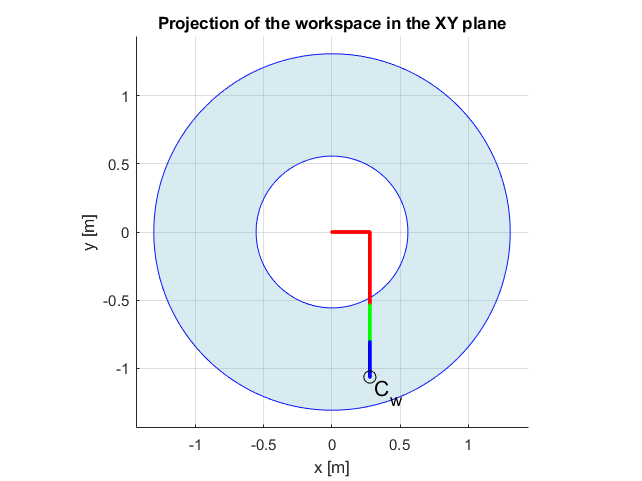

% Workspace
nPoints = [1000 100 200];

figure
workspace_XY_projection(L,angle,pos_limits,gcf,nPoints)

% Robot with all its axes in their median position (Cw: center of the working space)
Qcw = [median(pos_limits(1:2)); median(pos_limits(3:4)); median(pos_limits(5:6))];
Qcw = num2cell(Qcw);
plot_robot_bold_2D(Qcw,L,angle,gcf,[1 2])

set(gcf,'renderer','painters');
exportgraphics(gcf, strcat(plot_WS_directory,'\WS_XY.pdf'))

## Check Inverse Kinematics

Q = {0.5*pi; 0.2; 0.25*pi};
% Q = {0; pos_limits(4); 0};
[S,~] = dir_kin(Q,L,angle);

sol = 1;
Q_inv_kin = inv_kin(S,L,angle,sol);

Q0 = {0.4*pi; 0.25; 0.15*pi};
% Q0 = {0.2*pi; 0.4; -0.2*pi};
Q_inv_kin_numerical = inv_kin_numerical(S,L,angle,Q0);

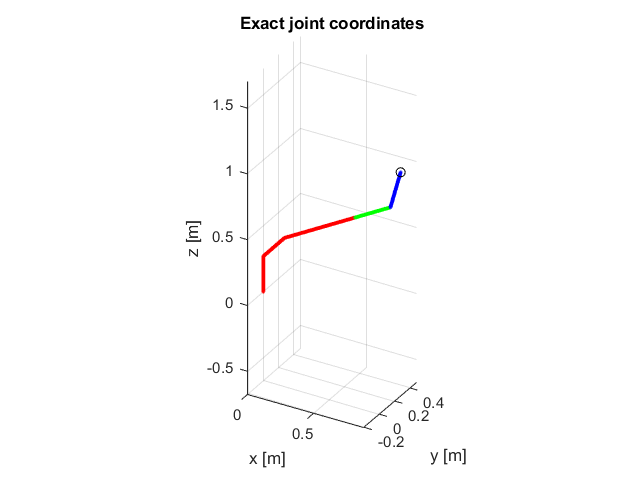

figure
plot_robot(Q,L,angle,gcf);
hold on
plot3(S{1},S{2},S{3},'ok');
grid on
axis equal
view(30,30)
xlabel('x [m]'); ylabel('y [m]'); zlabel('z [m]')
title('Exact joint coordinates')

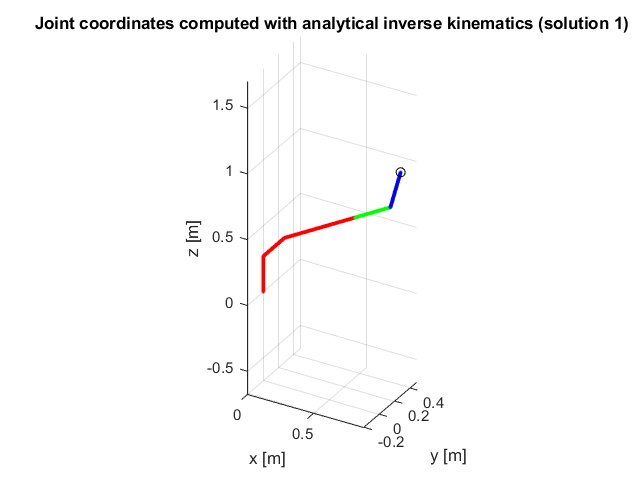

figure
plot_robot(Q_inv_kin,L,angle,gcf);
hold on
plot3(S{1},S{2},S{3},'ok');
grid on
axis equal
view(30,30)
xlabel('x [m]'); ylabel('y [m]'); zlabel('z [m]')
title('Joint coordinates computed with analytical inverse kinematics (solution 1)')

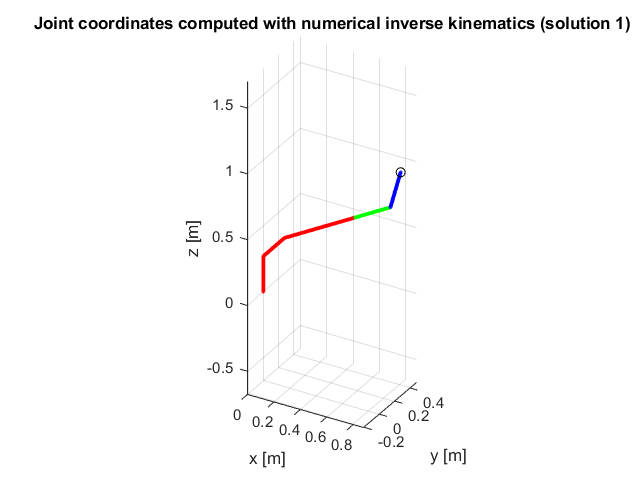

figure
plot_robot(Q_inv_kin_numerical,L,angle,gcf);
hold on
plot3(S{1},S{2},S{3},'ok');
grid on
axis equal
view(30,30)
xlabel('x [m]'); ylabel('y [m]'); zlabel('z [m]')
title('Joint coordinates computed with numerical inverse kinematics (solution 1)')

#### Double solution of the inverse kinematics

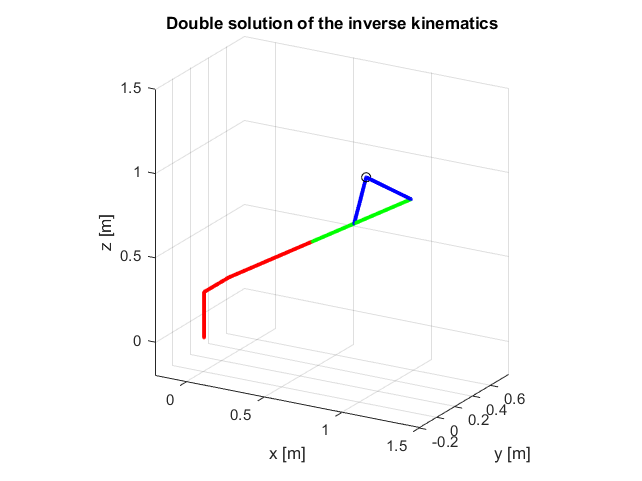

Q = {0.5*pi; 0.2; 0.25*pi};
[S,~] = dir_kin(Q,L,angle);

sol = 1;
Q_inv_kin_1 = inv_kin(S,L,angle,sol);
sol = 2;
Q_inv_kin_2 = inv_kin(S,L,angle,sol);

figure
plot_robot(Q_inv_kin_1,L,angle,gcf);
hold on
plot3(S{1},S{2},S{3},'ok');
plot_robot(Q_inv_kin_2,L,angle,gcf);
grid on
axis equal
view(30,20)
zlim([-0.2 1.5]); xlim([-0.2 1.5]); ylim([-0.2 0.8])
xlabel('x [m]'); ylabel('y [m]'); zlabel('z [m]')
title('Double solution of the inverse kinematics')

set(gcf,'renderer','painters');
exportgraphics(gcf, strcat(plot_WS_directory,'\double_solution.pdf'))